# Estimate Robot Pose with Scan Matching

This example demonstrates how to match two laser scans using the Normal Distributions Transform (NDT) algorithm [1]. The goal of scan matching is to find the relative pose (or transform) between the two robot positions where the scans were taken. The scans can be aligned based on the shapes of their overlapping features.

To estimate this pose, NDT subdivides the laser scan into 2D cells and each cell is assigned a corresponding normal distribution. The distribution represents the probability of measuring a point in that cell. Once the probability density is calculated, an optimization method finds the relative pose between the current laser scan and the reference laser scan. To speed up the convergence of the method, an initial guess of the pose can be provided. Typically, robot odometry is used to supply the initial estimate. 

If you apply scan matching to a sequence of scans, you can use it to recover a rough map of the environment that the robot traverses. Scan matching also plays a crucial role in other applications, such as position tracking and Simultaneous Localization and Mapping (SLAM).

## Load Laser Scan Data from File

%lidarScans2 = load('lidarScans.mat','lidarScans') %변수확인용임

% load lidarScans.mat


lidarScans3 = load('offlineSlamData.mat','scans'); %변경해서 테스트해보기 위해 lidarScans값에 데이터를 넣어줌
lidarScans3 = lidarScans3.scans(1:end)

lidarScans3 = 1×71 cell 배열
    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    {1×1 lidarScan}    


for idx = 1:numel(lidarScans3) %2~스캔횟수까지
    lidarScans(idx) = lidarScans3{idx};
end

The laser scan data was collected by a mobile robot in an indoor environment. An approximate floorplan of the area, along with the robot's path through the space, is shown in the following image.

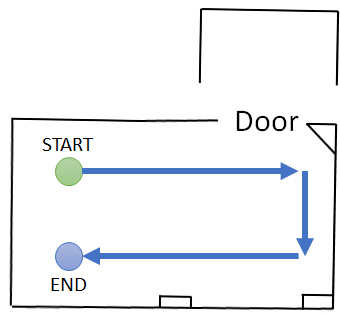

## Plot Two Laser Scans

Pick two laser scans to scan match from `lidarScans`. They should share common features by being close together in the sequence.

%referenceScan = lidarScans(180);
%currentScan = lidarScans(202);
referenceScan = lidarScans(36);
currentScan = lidarScans(41);

Display the two scans. Notice there are translational and rotational offsets, but some features still match.

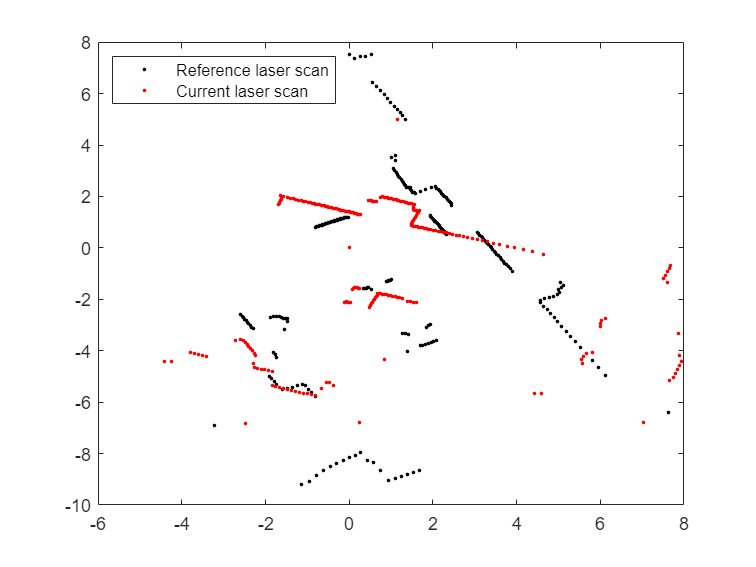

currScanCart = currentScan.Cartesian;
refScanCart = referenceScan.Cartesian;
figure
plot(refScanCart(:,1),refScanCart(:,2),'k.');
hold on
plot(currScanCart(:,1),currScanCart(:,2),'r.');
legend('Reference laser scan','Current laser scan','Location','NorthWest');

## Run Scan Matching Algorithm and Display Transformed Scan

Pass these two scans to the scan matching function. [`matchScans`](docid:nav_ref.bvlvwfu-1) calculates the relative pose of the current scan with respect to the reference scan.

transform = matchScans(currentScan,referenceScan)

transform =    -0.1345    0.2785   -0.0046


transform = matchScansGrid(currentScan,referenceScan)

transform =     2.8000   -1.7500   -0.7065


To visually verify that the relative pose was calculated correctly, transform the current scan by the calculated pose using [`transformScan`](docid:nav_ref.bvlvwih-1). This transformed laser scan can be used to visualize the result.

transScan = transformScan(currentScan,transform); % 오차가 너무 큼 그래서 위에 matchscangrid로 변경 그이후는 잘 매칭됨

Display the reference scan alongside the transformed current laser scan. If the scan matching was successful, the two scans should be well-aligned.

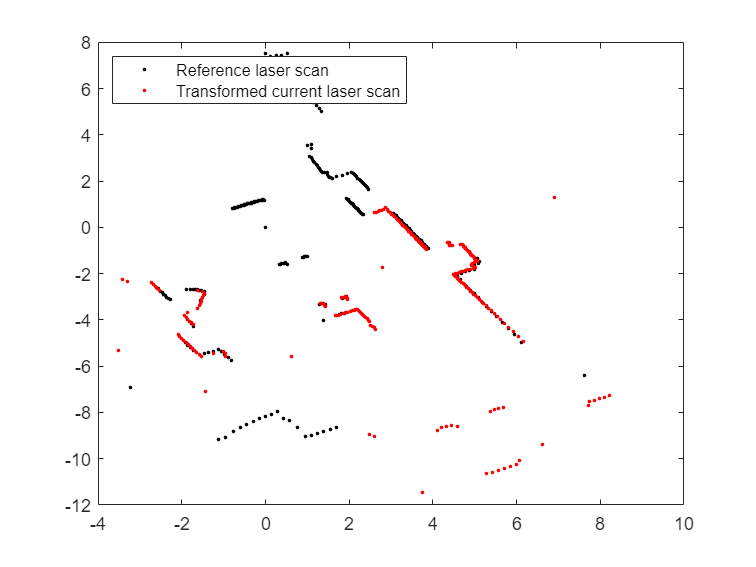

figure
plot(refScanCart(:,1),refScanCart(:,2),'k.');
hold on
transScanCart = transScan.Cartesian;
plot(transScanCart(:,1),transScanCart(:,2),'r.');
legend('Reference laser scan','Transformed current laser scan','Location','NorthWest');

## Build Occupancy Grid Map Using Iterative Scan Matching

If you apply scan matching to a sequence of scans, you can use it to recover a rough map of the environment. Use the [`occupancyMap`](docid:nav_ref.bvaw60t-1) class to build a probabilistic occupancy grid map of the environment.

Create an occupancy grid object for a 15 meter by 15 meter area. Set the map's origin to be [-7.5 -7.5].

map = occupancyMap(15,15,20);
map.GridLocationInWorld = [-7.5 -7.5]

map =   occupancyMap - 속성 있음:

   mapLayer Properties
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
                LayerName: 'probabilityLayer'
                 DataType: 'double'
             DefaultValue: 0.5000
      GridLocationInWorld: [-7.5000 -7.5000]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [-7.5000 -7.5000]
               Resolution: 20
                 GridSize: [300 300]
             XLocalLimits: [0 15]
             YLocalLimits: [0 15]
             XWorldLimits: [-7.5000 7.5000]
             YWorldLimits: [-7.5000 7.5000]


Pre-allocate an array to capture the absolute movement of the robot. Initialize the first pose as `[0 0 0]`. All other poses are relative to the first measured scan. 

위치이동경로를 담을곳을 0으로 초기화

numScans = numel(lidarScans);
initialPose = [0 0 0];
poseList = zeros(numScans,3);
poseList(1,:) = initialPose;  
transform = initialPose; 

Create a loop for processing the scans and mapping the area. The laser scans are processed in pairs. Define the first scan as reference scan and the second scan as current scan. The two scans are then passed to the scan matching algorithm and the relative pose between the two scans is computed. The `exampleHelperComposeTransform` function is used to calculate of the cumulative absolute robot pose. The scan data along with the absolute robot pose can then be passed into the [`insertRay`](docid:nav_ref.mw_6aad2bef-15f2-45cb-b5a7-8d0684ed5e02) function of the occupancy grid.

->스캔을 처리하고 영역을 매핑하기 위한 루프를 만듭니다. 레이저 스캔은 쌍으로 처리됩니다. 첫 번째 스캔을 참조 스캔으로 정의하고 두 번째 스캔을 현재 스캔으로 정의합니다. 그런 다음 두 스캔이 스캔 일치 알고리즘에 전달되고 두 스캔 사이의 상대 포즈가 계산됩니다. exampleHelperComposeTransform 함수는 누적 절대 로봇 포즈를 계산하는 데 사용됩니다. 그런 다음 절대 로봇 포즈와 함께 스캔 데이터를 점유 그리드의 insertRay 기능으로 전달할 수 있습니다.

% Loop through all the scans and calculate the relative poses between them
for idx = 2: numScans %2~스캔횟수까지
    % Process the data in pairs.
    referenceScan = lidarScans(idx-1);
    currentScan = lidarScans(idx);
    
    % Run scan matching. Note that the scan angles stay the same and do 
    % not have to be recomputed. To increase accuracy, set the maximum 
    % number of iterations to 500. Use the transform from the last
    % iteration as the initial estimate.
    [transform,stats] = matchScans(currentScan,referenceScan, ...
        'MaxIterations',500,'InitialPose',transform); 
    
    % The |Score| in the statistics structure is a good indication of the
    % quality of the scan match. 
    % 나타나는 스코어는 일치 품질임 ->예제는 스코어가 600점이었는데 27번째 이후로 오류때문인지 100점대가 최고긴함 계속
    % 오류가 발생하는 이유를 찾을 필요가 있음
    if stats.Score / currentScan.Count < 1.0
        disp(['Low scan match score for index ' num2str(idx) '. Score = ' num2str(stats.Score) '.']);
    end
    
    % Maintain the list of robot poses. 
    absolutePose = exampleHelperComposeTransform(poseList(idx-1,:),transform); %같이 첨부해준 예제 코드
    poseList(idx,:) = absolutePose;  %poseList에 위치 이동 정보값을 다 넣어줌
       
    % Integrate the current laser scan into the probabilistic occupancy grid.
    insertRay(map,absolutePose,currentScan,10);

end

Low scan match score for index 9. Score = 27.3407.
Low scan match score for index 10. Score = 64.848.
Low scan match score for index 11. Score = 69.1309.
Low scan match score for index 13. Score = 17.683.
Low scan match score for index 14. Score = 42.0444.
Low scan match score for index 15. Score = 35.965.
Low scan match score for index 16. Score = 2.1171e-10.
Low scan match score for index 17. Score = 20.038.
Low scan match score for index 18. Score = 1.6212.
Low scan match score for index 19. Score = 1.8789e-255.
Low scan match score for index 20. Score = 0.
Low scan match score for index 21. Score = 6.5917.
Low scan match score for index 22. Score = 14.221.
Low scan match score for index 23. Score = 3.1443.
Low scan match score for index 24. Score = 35.027.
Low scan match score for index 25. Score = 27.4217.
Low scan match score for index 26. Score = 1.4025e-15.
Low scan match score for index 27. Score = 104.9265.


다음 사용 중 오류가 발생함: nav.algs.internal.MapUtils.validatePose


오류 발생: nav.algs.internal.MapUtils.parseInsertRayInputs (70번 라인)
                        pose = nav.algs.internal.MapUtils.validatePose(varargin{1}, xlim, ...

오류 발생: occupancyMap/insertRay (1020번 라인)

## Visualize Map

Visualize the occupancy grid map populated with the laser scans.

figure
show(map);
title('Occupancy grid map built using scan matching results');

Plot the absolute robot poses that were calculated by the scan matching algorithm. This shows the path that the robot took through the map of the environment.

hold on
plot(poseList(:,1),poseList(:,2),'bo','DisplayName','Estimated robot position'); 
legend('show','Location','NorthWest')

## References

[1] P. Biber, W. Strasser, "The normal distributions transform: A new approach to laser scan matching," in Proceedings of IEEE/RSJ International Conference on Intelligent Robots and Systems (IROS), 2003, pp. 2743-2748

*Copyright 2019 The MathWorks, Inc.*